    % 模型建立（写出传递函数）
A = [-2.322, -0.3429;
    5.1958, -5.98];
B = [1.1293;
    1.9764];
C = [1.028, 0.1985];
D = 0.5862;
sys = ss(A, B, C, D);
model = tf(sys)

model =
 
  0.5862 s^2 + 6.42 s + 17.51
  ---------------------------
     s^2 + 8.302 s + 15.67
 
Continuous-time transfer function.



% 判断系统能控能观性
Q_c = ctrb(A, B);
RQ_c = rank(Q_c);
if RQ_c == 2
    disp '能控'
else
    disp '不能控'
end 

能控


% 使用Lyapunov第二方法判断系统稳定性
Q = eye(2);
P = lyap(A, Q);
flag = 0;
n = length(A);
for i = 1:n
    val = det(P(1:i, 1:i));
    if val <= 0
        flag = 1;
    end
end

if flag == 1
    disp '不稳定'
else
    disp '稳定'
end

稳定


% 求出状态反馈增益矩阵K和全维状态观测器并给出状态变量的实际值、观测值、误差以及输出响应曲线
J = [-4 -5];
K = acker(A, B, J)

K =     6.3623   -3.2822



p = [-6+3j, -6-3j];
G = acker(A', C', p)'

G =     4.1275
   -2.7459


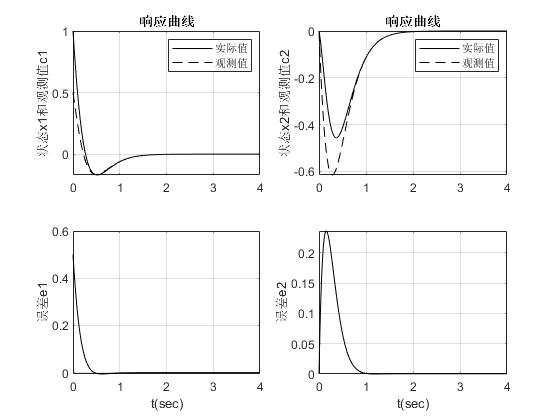


sys1 = ss([A-B*K, B*K; zeros(2), A-G*C], eye(4), eye(4), eye(4));

t = 0:0.01:4;
z = initial(sys1, [1; 0; 0.5; 0], t);

x1 = [1, 0, 0, 0]*z';
x2 = [0, 1, 0, 0]*z';
e1 = [0, 0, 1, 0]*z';
e2 = [0, 0, 0, 1]*z';

c1 = x1 - e1;
c2 = x2 - e2;

subplot(2,2,1);
plot(t, x1, '-k')
hold on
plot(t, c1, 'k--')
grid
title('响应曲线')
ylabel('状态x1和观测值c1')
legend('实际值','观测值')

subplot(2,2,2)
plot(t, x2, '-k')
hold on
plot(t, c2, 'k--')
grid
title('响应曲线')
ylabel('状态x2和观测值c2')
legend('实际值','观测值')

subplot(2,2,3)
plot(t, e1, 'k-')
grid
xlabel('t(sec)')
ylabel('误差e1')

subplot(2,2,4)
plot(t, e2, 'k-')
grid
xlabel('t(sec)')
ylabel('误差e2')